# **CAN 통신 연결**

clear;clc;
load("Adress_Detector.mat");
load("occGrid.mat");
scout = canChannel('PEAK-System', 'PCAN_USBBUS1');
% cam = webcam(3);

start(scout)

message = receive(scout, Inf, "OutputFormat", "timetable")

message = 808×8 timetable
       Time        ID     Extended       Name                  Data               Length      Signals       Error    Remote
    ___________    ___    ________    __________    __________________________    ______    ____________    _____    ______

    -0.012695초    593     false      {0×0 char}    {[       0 0 0 0 0 0 0 0]}      8       {0×0 struct}    false    false 
    -0.010867초    545     false      {0×0 char}    {[       0 0 0 0 0 0 0 0]}      8       {0×0 struct}    false    false 
    -0.010615초    785     false      {0×0 char}    {[0 2 142 52 0 2 226 112]}      8       {0×0 struct}    false    false 
    -0.010351초    594     false      {0×0 char}    {[       0 0 0 1 0 0 0 0]}      8       {0×0 struct}    false    false 
    -0.008688초    595     false      {0×0 char}    {[       0 0 0 0 0 0 0 0]}      8       {0×0 struct}    false    false 
    -0.006684초    596     false      {0×0 char}    {[       0 0 0 1 0 0 0 0]}      8       {0×0 struct}    fal

Table 3.5 Control Mode Setting Frame

TxMsg = canMessage(1057, false, 1);
TxMsg.Data = [1];
transmit(scout,TxMsg);

connect rplidar

hardwarex_init;
pRPLIDAR = CreateRPLIDAR();
% Check and modify the configuration file if needed...
[result] = ConnectRPLIDAR(pRPLIDAR, 'RPLIDAR0.txt')

result = 1

# **SLAM**


[slamObj,resolution, maxRange ]=SLAM(scans)

[scansSLAM,poses] = scansAndPoses(slamObj);

create Occupancy Map

occGrid = buildMap(scansSLAM,poses,resolution,maxRange);
figure
show(occGrid);impixelinfo;
title('Occupancy Map')

# **path planning**

**HybridAStar**

prompt = 'What is the original value? ';
x = input(prompt)

x = 1202

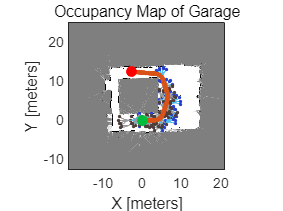


if x == 1201
     start = [ 0    0    0]; % pi: left 0: right pi/2: up -pi/2: down
     goal = [ 3.3   11.5  pi]; % 1: 3.5 12 pi (2.4, 3) 2: -4 11.8 3:-7.1 2.6 pi/2
     x = char('1201');
elseif x== 1202  
     start = [ 0    0    0]; % pi: left 0: right pi/2: up -pi/2: down
     goal = [ -2.8    12.5  pi]; % 1: 3.5 12 pi (2.4, 3) 2: -4 11.8 3:-7.1 2.6 pi/2
     x = char('1202');
elseif x == 1203
     start = [ 0    0    pi]; % pi: left 0: right pi/2: up -pi/2: down
     goal = [ -7.1    2.6  pi/2]; % 1: 3.5 12 pi (2.4, 3) 2: -4 11.8 3:-7.1 2.6 pi/2
     x = char('1203');
else 
     prompt = 'invalid adress';
end

title('Occupancy Map of Garage')

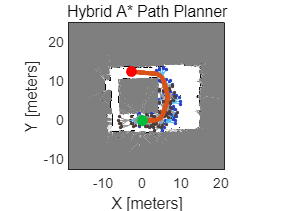

ss = stateSpaceSE2;
sv = validatorOccupancyMap(ss);

exmap = occupancyMap(occGrid, 20);
sv.Map = exmap;
sv.ValidationDistance = 0.4;
ss.StateBounds = [exmap.XWorldLimits; exmap.YWorldLimits; [-pi pi]];

planner = plannerHybridAStar(sv,'MinTurningRadius',2.4,'MotionPrimitiveLength',3);
  
refpath = plan(planner,start,goal);
path = refpath.States;
show(planner)


% [refpath,solnInfo] = RRTStar(occGrid,start,goal);

# **path following**  

% pause(7);
robotInitialLocation = path(1,1:2);

robotGoal = path(end,1:2);

initialOrientation = path(1,3);

robotCurrentPose = [robotInitialLocation initialOrientation]';

% Create a Kinematic Robot Model
robot = differentialDriveKinematics("TrackWidth", 0.4, ...
    "VehicleInputs", "VehicleSpeedHeadingRate", "WheelRadius", 0.085);


% Define the Path Following Controller
controller = controllerPurePursuit;
controller.Waypoints = path(:,1:2);
controller.DesiredLinearVelocity = 0.2; % 0.3
controller.MaxAngularVelocity = 3; %0.15
controller.LookaheadDistance = 0.6;

% Using the Path Following Controller, Drive the Robot over the Desired Waypoints
goalRadius = 0.1;
distanceToGoal = norm(robotInitialLocation - robotGoal);

% Initialize the simulation loop
sampleTime = 0.54; 
vizRate = rateControl(1/sampleTime);

while( distanceToGoal > goalRadius)

    [v, omega,~] = controller(robotCurrentPose);
    tic;
    while toc < 0.4
         
         flag = getScanData(pRPLIDAR);

        if flag ==1 
            
           turn_right(scout);
           break;

        end
   end
    
    if flag == 1
       
%            robotCurrentPose(3,1) = robotCurrentPose(3,1) -1.1;
%            start=robotCurrentPose';
%            goal = path(end,:);

           start = [6.25	7.4	 0.7]; % 가라
           goal = [ -2.8    11.3  pi];

           [path_re,planner]= HybridAStar(occGrid,start,goal);
           reset(vizRate);
           pure_pursuit_scout(path_re,scout,detector);
%          show(planner);
%          continue;
           break; 
    end
    
    vel = derivative(robot, robotCurrentPose, [v omega]);
    
    % Update the current pose
    robotCurrentPose = robotCurrentPose + vel*sampleTime;

    % Re-compute the distance to the goal.

    distanceToGoal = norm(robotCurrentPose(1:2) - robotGoal(:));

    
    %주행
    speed_8 = typecast(swapbytes(int16(v*1000)),"uint8");
    angle_8 = typecast(swapbytes(int16(omega*1000)),"uint8");
    
    TxMsg = canMessage(273, false, 8);
    TxMsg.Data = ([speed_8 angle_8 0 0 0 0]);
    transmit(scout,TxMsg);
    


    waitfor(vizRate);
   
end



%     [text,img] = getText(cam,detector);
% 
%     if contains(text,x) == 1
%             clear cam
%             [dists,cimg] = depth_dist(bboxes);
%             start=robotCurrentPose';
%             goal = start;
%             goal(1) = goal(1)-dists;
%             [path_re,~]= HybridAStar(occGrid,start,goal);
%             pure_pursuit_scout(path_re,scout);
%             break;
%     end



function [dists,cimg] = depth_dist(bboxes)

centroids = [round(bboxes(:, 1) + bboxes(:, 3) / 2), ...
    round(bboxes(:, 2) + bboxes(:, 4) / 2)];

get realsense
% Start streaming on an arbitrary camera with default settings
pipe = realsense.pipeline();
colorizer = realsense.colorizer();
pointcloud = realsense.pointcloud();
profile = pipe.start();

% Get streaming device's name
dev = profile.get_device();
name = dev.get_info(realsense.camera_info.name);

% 정합된 depth 이미지 추출.
align_to = realsense.stream.color;
align = realsense.align(align_to);

% Display image

    fs = pipe.wait_for_frames();
    depth = fs.get_depth_frame();
    % Colorize depth frame
    Color = colorizer.colorize(depth);
%     Color = fs.get_color_frame();
    Cdata = Color.get_data();
    aligned_frames = align.process(fs);
    aligned_depth_frame = aligned_frames.get_depth_frame();

    cimg = permute(reshape(Cdata',[3, Color.get_width(),Color.get_height()]), [3 2 1]);
    
    points = pointcloud.calculate(aligned_depth_frame);

    % Adjust frame CS to matlab CS
    vertices = points.get_vertices();
    X = permute(reshape(vertices(:,1,1),[aligned_depth_frame.get_width(), aligned_depth_frame.get_height()]),[2 1]);
    Y = permute(reshape(vertices(:,2,1),[aligned_depth_frame.get_width(), aligned_depth_frame.get_height()]),[2 1]);
    Z = permute(reshape(vertices(:,3,1),[aligned_depth_frame.get_width(), aligned_depth_frame.get_height()]),[2 1]);
    
    centroidsIdx = sub2ind([720,1280], centroids(:, 2), centroids(:, 1));

    centroids3D = [X(centroidsIdx)'; Y(centroidsIdx)'; Z(centroidsIdx)'];

    % Find the distances from the camera in meters.
    dists = sqrt(sum(centroids3D .^ 2));
end